Homework 1. 

Consider a system: $\ddot{x}=g tan\theta$, $\ddot{\theta}=\frac{l}{I_{yy}} u_3$

We assume state vactor as $\chi = (x,\dot{x}, \theta,\dot{\theta})'$,  then it follows that$\dot{\chi }= (\dot{x},\ddot{x}, \dot{\theta},\ddot{\theta})'=(\dot{x},g tan \theta, \dot{\theta},\frac{l}{I_{yy}}u_3)'$.

The implementation is as following, with initial state vector  $\chi_0 = (0, 0, 0.1, 0)$ and random input.

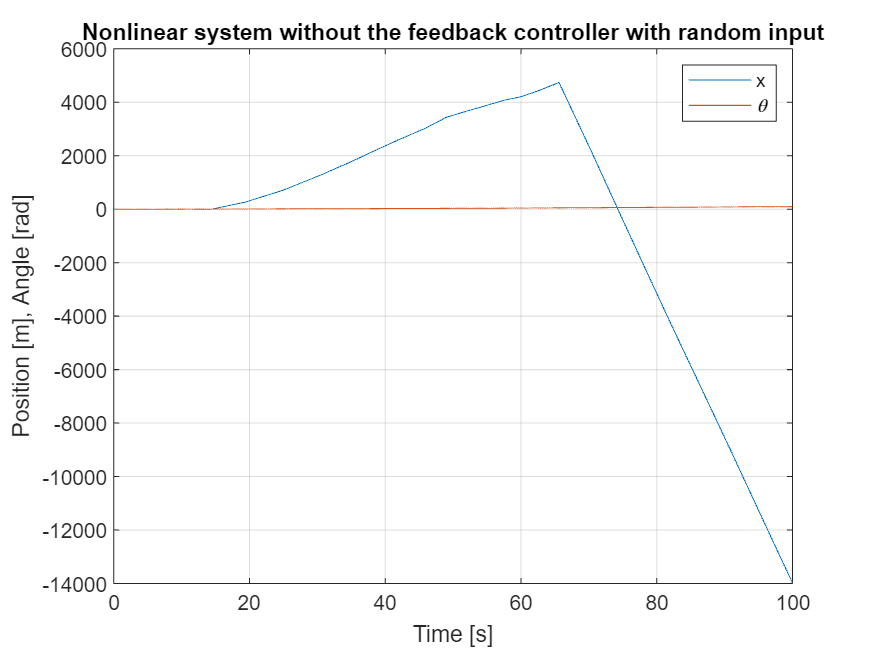

clear all; clc; close all;
% using numerical appoarch
chi_0 = [0;0;0.1;0;];       % initial vector
dt = 1/10;
t_span = 0:dt:100;                 % time vector
u_3 = rand(length(t_span),1)-0.5;       % random input
[chi_storage, dchi_storage] = model_generation ( chi_0, u_3, t_span); % display or off
checkplot(chi_storage, t_span)
title("Nonlinear system without the feedback controller with random input")

Task 3. Design a (stabilizing) feedback controller based on exact state linearization. 

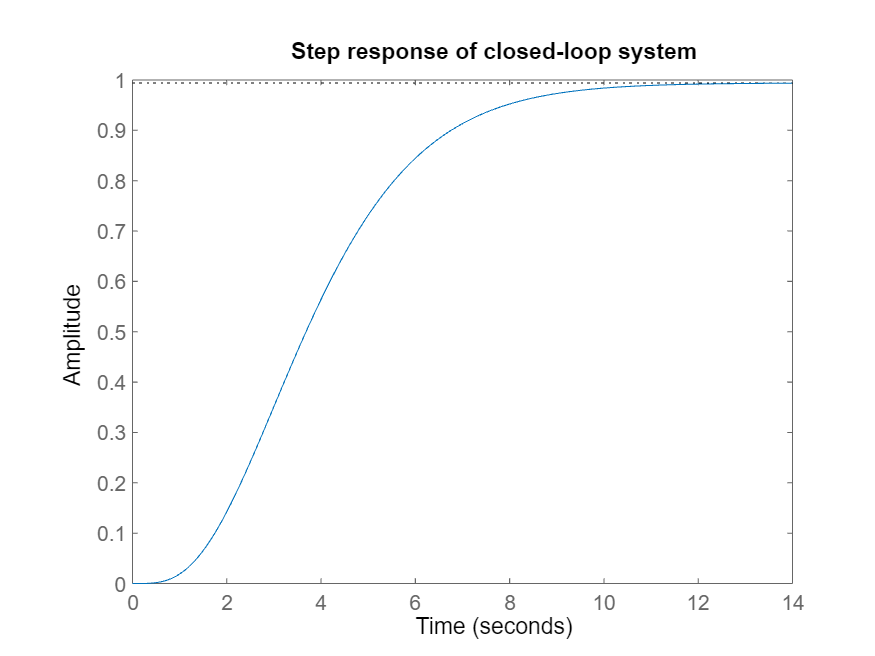

% parameter
g = 1;
l_I_yy = 1;

% determine feedback gain k
A=[0,1,0,0;
 0,0,1,0;
 0,0,0,1;
 0,0,0,0;];
B = [0;0;0;1];
C = [1,0,0,0];
D = 0;
sys = ss(A,B,C,D);
desired_pole = -1;
p = [desired_pole,desired_pole-0.001,desired_pole-0.002,desired_pole-0.003]; % desired pole
K = place(A,B,p);
Acl = A-B*K;
syscl = ss(Acl,B,C,D);
Pcl = pole(syscl); % check pole of c-l-sys
figure
step(syscl)
title("Step response of closed-loop system")

Task 4. Simulate the system with and without the feedback controller from for $ \eta _{ref} \equiv  0$, with initial condition $\chi_0 = (0, 0, 0.1, 0)$.

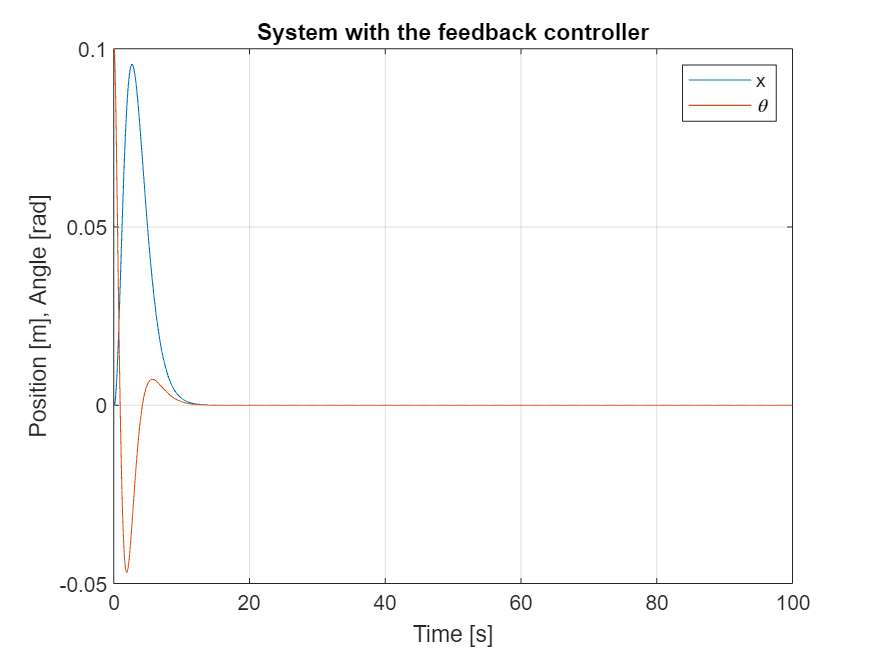

% set up
chi_ref = zeros(4,1); % \eta_ref = 0, from task discription
nu_ref = 0; % for the sake of simplicity, set nu_ref as zero (no feedforward)
k = round(K); % use feedback gain from Task 3

dchi_storage=[]; u_3_storage=[]; chi_storage=[chi_0']; % storage
chi_km1 = chi_0;
for i=1:length(t_span)
    % state vector
    u_3_k = (nu_ref + k*( chi_ref - chi_km1 ))/(g*l_I_yy*(sec(chi_km1(3)))^2); 
    [chi_km1 , dchi_km1] = state_vector(chi_km1, u_3_k, dt, [], []); 
    u_3_storage = [u_3_storage; double(u_3_k)];
    dchi_storage = [dchi_storage; double(dchi_km1')];
    chi_storage = [chi_storage; double(chi_km1')];
end

figure(Name="Display of Position \mathcal{x} and Angle \theta");
plot(t_span,chi_storage(1:end-1,1));
hold on;grid on;
plot(t_span,chi_storage(1:end-1,3));
legend("x","\theta")
xlabel("Time [s]")
ylabel("Position [m], Angle [rad]")
title("System with the feedback controller")

Task 5. Design a feedforward controller and reference trajectory generation based on exact state linearization.

Task 6. Implement the feedforward controller from Task 5 and the feedback controller from Task 2 for a transition from the state$\chi_0 = (0, 0, 0.1, 0)$ to the state $\chi_f = (1, 0, 0, 0)$.

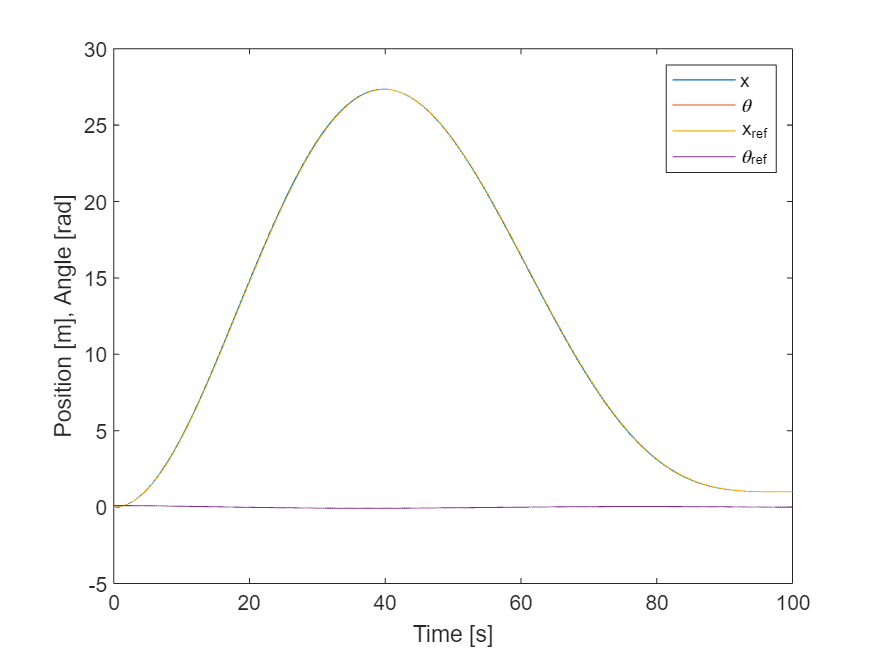

chi_0 = [0;0;0.1;0]; % initial state
eta_0 = exact_state_linearization(chi_0);
chi_f = [1;0;0;0;]; % final state
eta_f = exact_state_linearization(chi_f);
dchi_storage=[]; u_3_storage=[]; chi_storage=[chi_0']; 
eta_ref_storage =[eta_0'];

chi_km1 = chi_0;
for i=1:length(t_span)
    % state vector
    [eta_ref,nu_ref] = calculate_reference(eta_0,eta_f,t_span(i));
    u_3_ff = nu_ref*(cos(chi_km1(3)))^2-2*tan(chi_km1(3))*chi_km1(4)^2;
    u_3_fb = (k*( [eta_ref(1:2);atan(eta_ref(3));eta_ref(4)/(1+eta_ref(3)^2)] - chi_km1 ))/(g*l_I_yy*(sec(chi_km1(3)))^2); 
    [chi_km1 , dchi_km1] = state_vector(chi_km1, u_3_ff + u_3_fb, dt, [], []); 
    eta_ref_storage = [eta_ref_storage;double(eta_ref')];
    u_3_storage = [u_3_storage; double(u_3_ff + u_3_fb)];
    dchi_storage = [dchi_storage; double(dchi_km1')];
    chi_storage = [chi_storage; double(chi_km1')];
end
chi_ref_storage = [eta_ref_storage(:,[1:2]),atan(eta_ref_storage(:,3)),...
    eta_ref_storage(:,4)./(1+eta_ref_storage(:,3).^2)];
figure
plot(t_span,chi_storage(1:end-1,[1,3]));hold on
plot(t_span,chi_ref_storage(1:end-1,[1,3]))
    legend("x","\theta","x_{ref}","\theta_{ref}")
    xlabel("Time [s]")
    ylabel("Position [m], Angle [rad]")

function [eta_ref,nu_ref] = calculate_reference(eta_0,eta_f,t_i)
% b = [1,t,t^2,....t^7]; r dimension = 2*r, max.poly. is 2*r-1
% B = [b;db,ddb,dddb];
% [eta_ref;nu_ref]=[B;ddddb]*[B(t_0);B(t_f)]^(-1)*[eta_0;eta_f];
syms t
B = [t.^(0:7);diff(t.^(0:7),t,1);diff(t.^(0:7),t,2);diff(t.^(0:7),t,3);];
temp = [subs(B,t,t_i);subs(diff(t.^(0:7),t,4),t,t_i)]*[subs(B,t,0);subs(B,t,100)]^(-1)*[eta_0;eta_f];
eta_ref = temp(1:4);
nu_ref = temp(end);
end

function [chi_storage, dchi_storage] = model_generation ( chi_km1, u_3, t)
%This function generate the state vector and its derivatives along given
%time scope, or it at next time step. The euler backwards discretization
%is used. The state function assumed to be nonlinear.
%chi_km1: previous state vector 
%u_3: input vector within time scope
%t: time scope
%chi_storage: state vector within time scope
%dchi_storage: derivative of state vector within time scope

    % parameter
    g = 1;
    l_I_yy = 1;

    % storage
    dchi_storage=[];chi_storage=[chi_km1'];
    for i=1:length(t)
        % generate state vector
        [chi_k , dchi_km1] = state_vector(chi_km1, u_3(i), t(2)-t(1), g, l_I_yy); 
        dchi_storage = [dchi_storage; dchi_km1'];
        chi_storage = [chi_storage; chi_k'];
        chi_km1 = chi_k;
    end    
end
function [chi_k , dchi_km1] = state_vector(chi_km1, u_3, dt, g, l_I_yy)
    if isempty(g)     % parameter default
        g = 1;
        l_I_yy = 1;
    end
    dchi_km1= [chi_km1(2);g*tan(chi_km1(3));chi_km1(4);l_I_yy * u_3];
    chi_k = chi_km1 + dchi_km1 * dt;
    chi_k = double(chi_k);
    dchi_km1 = double(dchi_km1);
end
function [eta] = exact_state_linearization(chi)
    g = 1;
    l_I_yy = 1;
    dt = 1;
    eta = [chi(1);chi(2); g * tan(chi(3)); g * sec(chi(3))^2 * chi(4)];
end
function checkplot(chi_storage, t)
    figure(Name="Display of Position \mathcal{x} and Angle \theta");
    plot([0,t],chi_storage(:,1));
    hold on;grid on;
    plot([0,t],chi_storage(:,3));
    legend("x","\theta")
    xlabel("Time [s]")
    ylabel("Position [m], Angle [rad]")
end